# **Optimising the classification of feature-based attention in frequency-tagged electroencephalography data**

**Created by Angela I. Renton. Email: angie.renton23@gmail.com**

## Background

This script was written to apply several machine learning approaches to classify the target of  feature-selective attention using short windows of single-trial EEG data. This live script both trains and tests a series of algorithms, and allows you to select the training parameters. 

The data analysed in this script was collected while participants performed a dot motion discrimination task on a set of flickering dots. We recorded continuous EEG data while participants performed this task (see **a **in figure below). Each 17 s trial consisted of a 2 s cue indication which colour participants should focus on, followed by a 15 s period which contained 5 coherent motion epochs (see **b **in figure below). Dots were presented either with a distractor present, such that black and white dots, flickering at 6 & 7.5 Hz (colour and frequency were counterbalanced) occurred concurrently, or individually, such that only dots of one colour flickering at one frequency were presented at once (see **c **in figure below). See the associated Data Descriptor for a detailed account of the methods used to collect the data analysed here (link to come). 

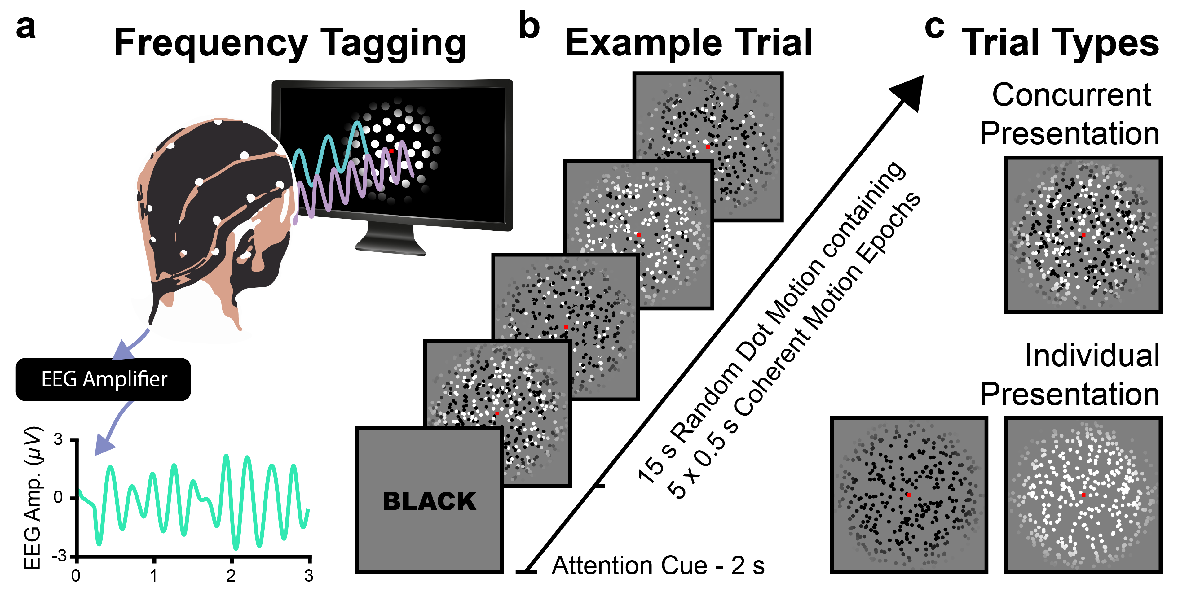

This script applies a processing pipeline, subjecting the data to a number of different analysis approaches and machine learning techniques in order to accurately classify the target of attention using single trial, frequency-tagged EEG data. The pipeline is as follows:

- Data processing (**a** in figure below): We extract epochs of sliding window data from each trial using a 0.25 s interval, and sliding window sizes ranging from 0.25 s to 4.00 s. 

- Feature extraction (**b** in figure below): We zero-pad the data to achieve 0.5 Hz spectral resolution, and apply Fast-Fourier Transforms (FFT's) to these epochs, extracting the amplitude at the flicker frequencies, their harmonics, and in the alpha range. 

- Training and testing machine learning algorithms (**c-h** in figure below):  We use a number of different machine learning techniques to classify the attended frequency using different combinations of the FFT data. 

- Collate results: We load the results from each individual participant and classifier to aggregate these into a single results file for further statistical analysis. 

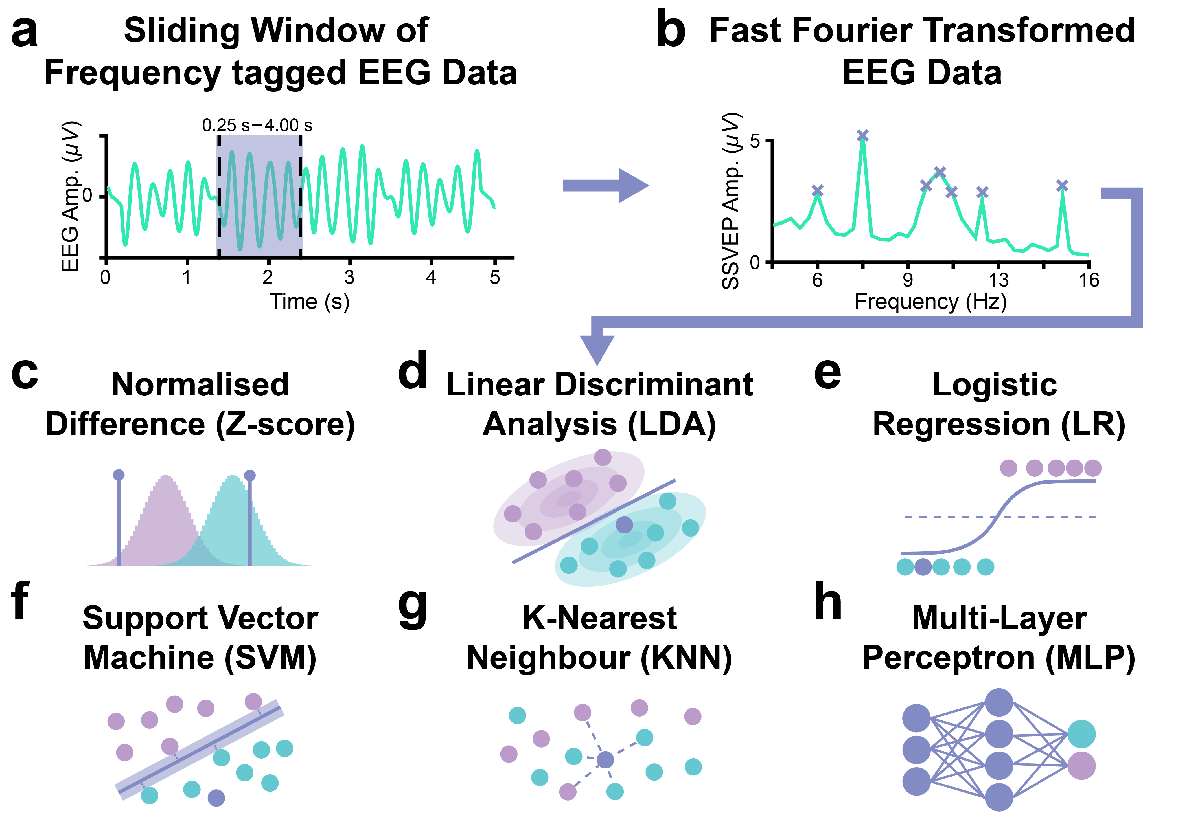

## Dependencies 

This live script relies on the scripts in the "*functions/" *folder and data from either the *"data/" or "results/" *folders which should have been downloaded along with the script. 

If you have downloaded the "*results*/" data folder, EEG data corresponding to each trial should be loaded from .mat files in that folder, and you will be able to run the data collation portion of the script without having individually run each algorithm on each participant. 

If the results folder is missing or empty, this script will recreate these files by loading and pre-processing the raw EEG data from the "*data/*" folder. The function which loads the raw EEG data to perform this has been written using functions from the fieldtrip toolbox ([http://www.fieldtriptoolbox.org/](http://www.fieldtriptoolbox.org/)).

*If you would prefer not to download fieldtrip, you will need to change the data directory to the "sourcedata" directory (subfolder within the data folder), which contains EEG data for each participant in a .mat format. You will also need to edit the get_eeg function to load these .mat formatted data instead of using fieldtrip. *

## **Getting Started**

### **Housecleaning**

We'll clean up matlab before running anything so that we start with a blank workspace and command window, and without any figures open. We'll also add the "functions" directory, which contains all of the functions we've written to run our analyses (feel free to explore these functions to better understand the mechanics of this script). Finally, we'll set the random seed so that our results are reproducible.  

clear
clc
close all

% Add path to custom-written functions
addpath([pwd '/Functions/']);

% set random seed.
rng('default') % For reproducibility

### Set training parameters

We have the option to train and test a number of different classification algorithms. Which would you like to run? 

runopts.zscore =true; % Z-score
runopts.LDA = 1; % Linear discriminant Analysis
runopts.KNN =1; % K-Nearest Neighbours
runopts.MLP = 1; % Multi layer perceptron
runopts.SVM = 1; % Support vector machine with RBF kernel
runopts.LR_L1 = true; % Logistic regression w/ lasso regularization
runopts.LR_L2 = true; % Logistic regression w/ ridge regularization

Data exist for trials when the distractor colour was both present (i.e. participants had to engage their feature-based attention) and absent. Which data would you like to train the classifier on? *Note that when testing the classifier on distractor absent data, you are essentialy asking which colour was presented (black or white dots), rather than which colour participants were attending to.* 

runopts.traindat =1;
runopts.testdat =1;

This live script has been written to execute training and testing for each individual participant and to collate results across participants. Which sections of the code would you like to run?

runopts.individuals = true; % Run the analyses on individual participants
runopts.collate = 1; % Collate results across participants

To prevent participants attention from being captured to the uncued colour, coherent motion epochs were only presented in the trained colour. These motion epochs were only ever created usning non-flickering dots, and therefore cannot affect the SSVEP signal. To be safe through, we can choose to exlude data corresponding to the timing of coherent motion epochs from training and testing. Would you like to do this? 

runopts.excludemotepochs = 1; 

### Setup Metadata

There is a lot of metadata associated with these data. We'll use a function "setup_metadata" to store this under the structure *sets*. We'll pass this structure around to all the other functions that need this information. Feel free to browse the *setup_metadata* script in the functions folder to find out more about this information. 

sets = setup_metadata();

## Loop through participants

There are a lot of custom written functions executed in this section, feel free to explore the code in these functions in more detail to get a deeper understanding of the mechanics of our analysis approach.  

We're ready to run the analysis for each individual participant! 

if runopts.individuals %This section should only run if we've specified above that we want to run the classifiers for individual participants.        
    for SUB = 1:sets.n.sub_ids

### Participant specific settings

There were two participants for whom there were technical difficulties with the recording. We'll skip over them:        

        if ismember(SUB, [7 19]) % Exclude excluded participants 
            continue
        end            

We need to update our metadata to describe which participant we're currently analysing, and specify the sub-directories in which there data are stored. 

        % Setup strings and directories for this participant.
        runopts.subject = SUB;
        disp(['Running subject :' num2str(runopts.subject)])
        sets = setup_subject_directories(sets, runopts);        

### Load and organise EEG data

Now that we have our directories set correctly, we can load this participant's EEG data, and extract the labels and data for each trial. This information will be stored in the structure "trialeeg". 

        disp('Loading EEG data')
        trialeeg = get_eeg(sets);       

### Extract sliding window data

This analysis is performed on sliding windows of single trial EEG data. Lets collect and label these sliding windows from the full trial data. 

        disp('Extracting sliding window chunks')
        [chunkeeg, chunklabels] = get_slidingwindoweeg(trialeeg,sets);

### Get features

For each of our sliding windows, we'll apply a Fast-Fourier Transform and extract the amplitudes at the frequencies of interest to be our features for classification. 

        disp('Calculating features')
        chunk_features = get_features(chunkeeg, sets);

### Run decoding analysis

Now that we have our feature vectors and their corresponding labels, lets train the machine learning algorithms that we specified to classify these data, and evaluate their performance. 

        for ii_method = 1:sets.n.methods
            decodestring = sets.str.methods{ii_method};
            if runopts.(decodestring)
                run_ML(chunk_features, chunklabels, sets, runopts, decodestring)
            end
        end        
    end
end

## Collate Results

Now that we've run our classification algorithms for each participant, let's collate our results so we can visualise them and store them for further analysis. 

%% Collate results across subjects
if runopts.collate
    % Collate for each method
    for ii_method = 1:sets.n.methods
        decodestring = sets.str.methods{ii_method};
        if runopts.(decodestring)
            % Get individual subject data
            ACCMEAN_ALL = collate_MLACC(sets, runopts, decodestring);
            
            % Plot data
            plot_groupresults(ACCMEAN_ALL, sets, runopts, decodestring)
        end
    end
end

## Results

If you're curious, here's a summary of the results across all of those training conditions: